# 平衡控制+腿部控制

## 0 准备工作

[简化模型动力学分析](matlab:open('./simplified_dynamic.mlx'))

[腿部五连杆运动学/动力学分析](matlab:open('./leg_analysis.mlx'))

clear; clc;
run("./simplified_dynamic.mlx");
run("./leg_analysis.mlx");

## 1 机器人参数与系统建模

机器人各质量、尺寸参数主要通过机械图纸测量得到，其中腿部惯量和质心位置简化近似为腿长 $l$ 的线性函数

单侧腿平面转动惯量 


$$I_l\approx0.4l+0.07\ (kg\cdot m^2)$$


腿部质心位置


$$l_b\approx0.218l+0.075\ (m)$$



$$l_w=l-l_b\approx0.782l-0.075\ (m)$$


param_t = struct( ...
  "g", 9.81, ...
  "m_w", 1.01, ...
  "I_w", 1248e-6, ...
  "m_l", 2*2.4, ...
  "I_l", @(l)2*(0.4*l+0.07), ...
  "m_b", 14.76, ...
  "I_b", 268943e-6, ...
  "R_w", 60e-3, ...
  "l_w", @(l)0.218*l+0.075, ...
  "l_b", @(l)0.782*l-0.075, ...
  "l_c", 1e-3); % -7e-3~10e-3

model_t = struct( ...
  "A", @(l)double(subs(A_sym,{g,m_w,I_w,m_l,I_l,m_b,I_b,R_w,l_w,l_b,l_c}, ...
          {param_t.g,param_t.m_w,param_t.I_w,param_t.m_l,param_t.I_l(l), ...
           param_t.m_b,param_t.I_b,param_t.R_w,param_t.l_w(l),param_t.l_b(l), ...
           param_t.l_c})), ...
  "B", @(l)double(subs(B_sym,{g,m_w,I_w,m_l,I_l,m_b,I_b,R_w,l_w,l_b,l_c}, ...
          {param_t.g,param_t.m_w,param_t.I_w,param_t.m_l,param_t.I_l(l), ...
           param_t.m_b,param_t.I_b,param_t.R_w,param_t.l_w(l),param_t.l_b(l), ...
           param_t.l_c})), ...
  "C", eye(6));

## 2 腿部运动学

leg_t = struct( ...
  "l_1_a", 0.075, ...
  "l_1_u", 0.15, ...
  "l_1_d", 0.3, ...
  "l_2_a", 0.075, ...
  "l_2_u", 0.15, ...
  "l_2_d", 0.3);
% [phi1;phi2]=ikine(l,θ)
leg_t.ikine = matlabFunction(subs([phi_1_sym;phi_2_sym], ...
                {l_1_a,l_1_u,l_1_d,l_2_a,l_2_u,l_2_d}, ...
                {leg_t.l_1_a,leg_t.l_1_u,leg_t.l_1_d, ...
                 leg_t.l_2_a,leg_t.l_2_u,leg_t.l_2_d}));
% [x1;x2]=f_xi(phi)
leg_t.xi = @(phi)[leg_t.l_1_a-leg_t.l_1_u*cos(phi(1))
                  leg_t.l_2_a-leg_t.l_2_u*cos(phi(2))];
% [y1,y2]=f_yi(phi)
leg_t.yi = @(phi)[leg_t.l_1_u*sin(phi(1))
                  leg_t.l_2_u*sin(phi(2))];
% xe=f_xe(x1,x2,y1,y2)
leg_t.xe = matlabFunction(subs(x_e_sym,{l_1_d,l_2_d}, ...
                         {leg_t.l_1_d,leg_t.l_2_d}));
% ye=f_ye(x1,x2,y1,y2)
leg_t.ye = matlabFunction(subs(y_e_sym,{l_1_d,l_2_d}, ...
                         {leg_t.l_1_d,leg_t.l_2_d}));
% [l;θ]=fkine(xe,ye)
leg_t.fkine = @(xe,ye)[sqrt(xe^2+ye^2);atan2(xe,ye)];
% jacobian matrix
leg_t.Pphi1Pl = @(l,theta,phi,xe,ye,xi,yi,li_u)1/li_u(1) ...
                      *((xe+xi(1))*sin(theta)+(ye-yi(1))*cos(theta)) ...
                      /(-(xe+xi(1))*sin(phi(1))+(ye-yi(1))*cos(phi(1)));
leg_t.Pphi1Ptheta = @(l,theta,phi,xe,ye,xi,yi,li_u)l/li_u(1) ...
                      *((xe+xi(1))*cos(theta)-(ye-yi(1))*sin(theta)) ...
                      /(-(xe+xi(1))*sin(phi(1))+(ye-yi(1))*cos(phi(1)));
leg_t.Pphi2Pl = @(l,theta,phi,xe,ye,xi,yi,li_u)1/li_u(2) ...
                      *((xe-xi(2))*sin(theta)+(ye-yi(2))*cos(theta)) ...
                      /((xe-xi(2))*sin(phi(2))+(ye-yi(2))*cos(phi(2)));
leg_t.Pphi2Ptheta = @(l,theta,phi,xe,ye,xi,yi,li_u)l/li_u(2) ...
                      *((xe-xi(2))*cos(theta)-(ye-yi(2))*sin(theta)) ...
                      /((xe-xi(2))*sin(phi(2))+(ye-yi(2))*cos(phi(2)));
leg_t.jacob = @(l,theta,phi,xe,ye,xi,yi) inv([ ...
    leg_t.Pphi1Pl(l,theta,phi,xe,ye,xi,yi,[leg_t.l_1_u;leg_t.l_2_u]), ...
    leg_t.Pphi1Ptheta(l,theta,phi,xe,ye,xi,yi,[leg_t.l_1_u;leg_t.l_2_u]); ...
    leg_t.Pphi2Pl(l,theta,phi,xe,ye,xi,yi,[leg_t.l_1_u;leg_t.l_2_u]), ...
    leg_t.Pphi2Ptheta(l,theta,phi,xe,ye,xi,yi,[leg_t.l_1_u;leg_t.l_2_u])]);

正运动学插值拟合（降低计算量）

% leg forward kinematic interpolation fitting
leg_fit_t = struct;
[leg_fit_t.phi1,leg_fit_t.phi2] = meshgrid((120:5:210)/180*pi, ...
                                           (120:5:210)/180*pi);
for i = 1:size(leg_fit_t.phi1,1)
  for j = 1:size(leg_fit_t.phi1,2)
    xi = leg_t.xi([leg_fit_t.phi1(i,j),leg_fit_t.phi2(i,j)]);
    yi = leg_t.yi([leg_fit_t.phi1(i,j),leg_fit_t.phi2(i,j)]);
    leg_fit_t.xe(i,j) = leg_t.xe(xi(1),xi(2),yi(1),yi(2));
    leg_fit_t.ye(i,j) = leg_t.ye(xi(1),xi(2),yi(1),yi(2));
  end
end
% leg_fit.A=[1,phi1,phi2,phi1^2,phi2^2,phi1*phi2]
leg_fit_t.A = [ones(size(leg_fit_t.phi1(:))),leg_fit_t.phi1(:), ...
               leg_fit_t.phi2(:),leg_fit_t.phi1(:).^2, ...
               leg_fit_t.phi2(:).^2,leg_fit_t.phi1(:).*leg_fit_t.phi2(:)];
leg_fit_t.k_xe = leg_fit_t.A\leg_fit_t.xe(:);
leg_fit_t.k_ye = leg_fit_t.A\leg_fit_t.ye(:);
leg_fit_t.xe = @(phi)[1,phi(1),phi(2),phi(1)^2,phi(2)^2,phi(1)*phi(2)]* ...
                      leg_fit_t.k_xe;
leg_fit_t.ye = @(phi)[1,phi(1),phi(2),phi(1)^2,phi(2)^2,phi(1)*phi(2)]* ...
                      leg_fit_t.k_ye;
leg_fit_t.fkine = @(phi)leg_t.fkine(leg_fit_t.xe(phi),leg_fit_t.ye(phi));
leg_fit_t.jacob = @(l,theta,phi)leg_t.jacob(l,theta,phi, ...
       leg_fit_t.xe(phi),leg_fit_t.ye(phi),leg_t.xi(phi),leg_t.yi(phi));

% figure;
% subplot(1,2,1); hold on; view(3);
% mesh(leg_fit_t.phi1,leg_fit_t.phi2,leg_fit_t.xe);
% plot3(leg_fit_t.phi1(:),leg_fit_t.phi2(:),leg_fit_t.A*leg_fit_t.k_xe,".");
% xlabel("phi1"); ylabel("phi2"); zlabel("x_e");
% subplot(1,2,2); hold on; view(3);
% mesh(leg_fit_t.phi1,leg_fit_t.phi2,leg_fit_t.ye);
% plot3(leg_fit_t.phi1(:),leg_fit_t.phi2(:),leg_fit_t.A*leg_fit_t.k_ye,".");
% xlabel("phi1"); ylabel("phi2"); zlabel("y_e");
% set(gcf,"position",[0,0,600,300]);

disp(leg_fit_t.k_xe);

   -0.0000
   -0.2983
    0.2983
    0.0367
   -0.0367
   -0.0000


disp(leg_fit_t.k_ye);

    1.0738
   -0.2040
   -0.2040
    0.0001
    0.0001
    0.0414


## 3 控制器设计

### 3.1 平衡控制

状态反馈控制器

$\mathbf{u}=K_{2\times6}(\mathbf{x}_d-\mathbf{x})$    (1)

状态反馈矩阵 K 通过 LQR 计算得到，代价函数

$J=\int_{0}^{\infty}\left(x^TQx+u^TRu\right)dx$    (2)

根据 LQR 可以得到状态反馈矩阵 K

$K=R^{-1}B^TP$    (3)

其中 P 满足 Riccati 方程

$A^TP+PA+PBR^{-1}B^TP+Q=0$    (4)

由于 $A,\ B$ 是关于腿长 $l$ 的函数，为了降低运算量，采用插值拟合的方式得到状态反馈矩阵 K

$K(l)=k_{K,0}+k_{K,1}l+k_{K,2}l^2$    (5)

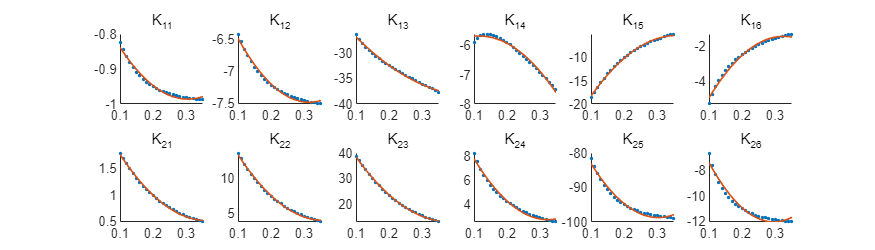

% solve LQR
balance_controller_t = struct;
l_list = 0.1:0.01:0.35;
for i = 1:size(l_list,2)
  balance_controller_t.ss_WBR = ss(model_t.A(l_list(i)), ...
                                   model_t.B(l_list(i)),model_t.C,0);
  balance_controller_t.Q = diag([10,5e2,2e3,50,1e4,100]);
  balance_controller_t.R = diag([10,1]);
  balance_controller_t.K_list(:,:,i) = lqr(balance_controller_t.ss_WBR, ...
                                           balance_controller_t.Q, ...
                                           balance_controller_t.R);
end
% least square fit
for i = 1:size(balance_controller_t.K_list,1)
  for j = 1:size(balance_controller_t.K_list,2)
    Kij = balance_controller_t.K_list(i,j,:);
    k = [ones(size(l_list));l_list;l_list.^2]'\Kij(:);
    balance_controller_t.k(i,j,1) = k(1);
    balance_controller_t.k(i,j,2) = k(2);
    balance_controller_t.k(i,j,3) = k(3);
  end
end
% Kij(l), for plot only
balance_controller_t.Kfit_ij = @(l,i,j)balance_controller_t.k(i,j,1) ...
                                      +balance_controller_t.k(i,j,2).*l ...
                                      +balance_controller_t.k(i,j,3).*l.^2;
% feedback control matrix: Kfit(l)
balance_controller_t.Kfit = @(l)balance_controller_t.k(:,:,1) ...
                               +balance_controller_t.k(:,:,2).*l ...
                               +balance_controller_t.k(:,:,3).*l.^2;

figure;
m = size(balance_controller_t.K_list,1);
n = size(balance_controller_t.K_list,2);
for i = 1:m
  for j = 1:n
    Kij = balance_controller_t.K_list(i,j,:);
    subplot(m,n,(i-1)*n+j); hold on; 
    title("K_{"+string(i)+string(j)+"}");
    plot(l_list,Kij(:),".");
    plot(l_list,balance_controller_t.Kfit_ij(l_list,i,j),"LineWidth",1);
  end
end
set(gcf,"position",[0,0,700,200]);

### 3.2 腿部控制

控制目标：调节腿部支持力控制左右腿长度，使机体保持特定高度&滚转角，并起到悬挂减震的作用

输入：机体目标滚转角(roll) & 目标腿长(平均值) $(\psi_{b,d},l_d)$

输出：左右腿支持力 $(F_{bl.l},F_{bl,r})$

反馈：机体滚转角 & 左右腿长度 $(\psi_b,l_l,l_r)$

控制器：PD控制+前馈

在建模过程中将腿部的并联机构进行了简化，控制量解耦为沿腿长方向的支持力和机体-腿关节处的转矩。而实际控制中腿部的执行器为2个关节电机，因此需要根据腿部动态静力学将支持力和转矩映射到关节电机转矩（[腿部五连杆运动学/动力学分析](matlab:open('./leg_analysis.mlx'))，式17）。

leg_controller_t = struct;
leg_controller_t.psi.kp = 0;
leg_controller_t.psi.ki = 0;
leg_controller_t.psi.kd = 0;
leg_controller_t.l.kp = 300;
leg_controller_t.l.ki = 10;
leg_controller_t.l.kd = 150;

### 3.3 控制器参数

disp(balance_controller_t.Q)

          10           0           0           0           0           0
           0         500           0           0           0           0
           0           0        2000           0           0           0
           0           0           0          50           0           0
           0           0           0           0       10000           0
           0           0           0           0           0         100


disp(balance_controller_t.R)

    10     0
     0     1


% K(l) = k(:,:,1)+k(:,:,2)*l+k(:,:,3)*l^2
disp(balance_controller_t.k)

(:,:,1) =
   -0.6578   -5.3292  -19.4966   -6.1604  -30.2483   -8.7311
    2.8963   22.0211   60.0414   13.3426  -63.8742   -1.5015
(:,:,2) =
   -2.1589  -13.7424  -83.1162    8.2557  138.9527   44.8030
  -13.1366 -101.2443 -248.5760  -65.3543 -230.0723  -71.4180
(:,:,3) =
    3.5490   21.8760   91.2113  -35.3716 -194.0204  -69.0502
   18.1246  141.3095  326.9953  100.3417  379.8627  121.0402


disp(leg_controller_t.psi)

    kp: 0
    ki: 0
    kd: 0


disp(leg_controller_t.l)

    kp: 300
    ki: 10
    kd: 150


## 4 simulink仿真

[simulink仿真](matlab:open('./balance_and_leg_control.slx'))

### 仿真结果

状态变量

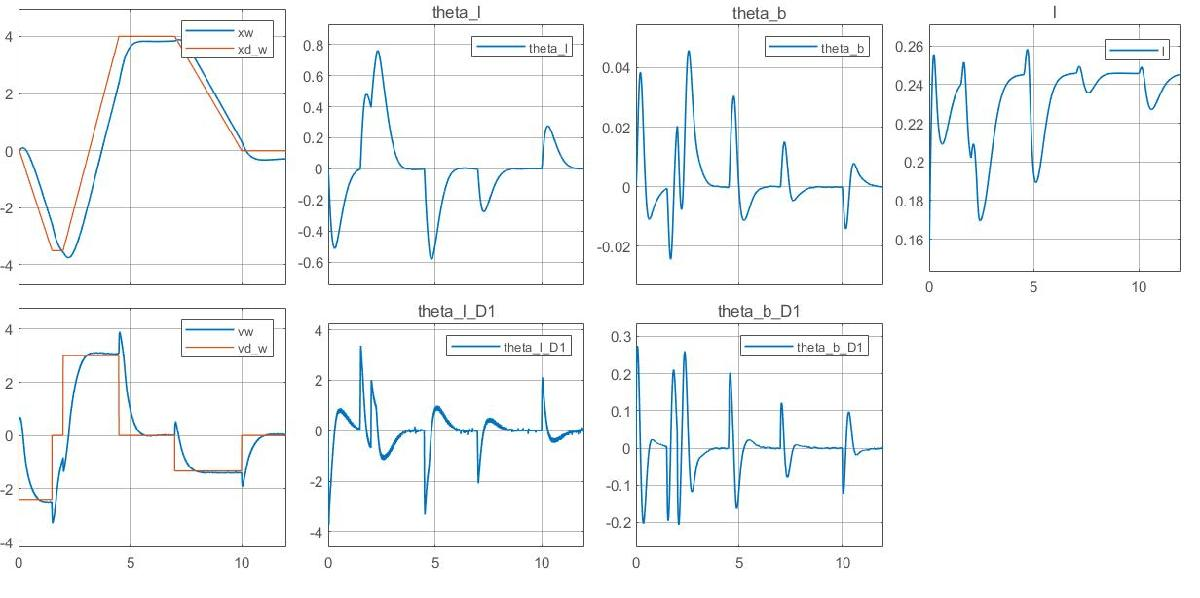

控制器输出

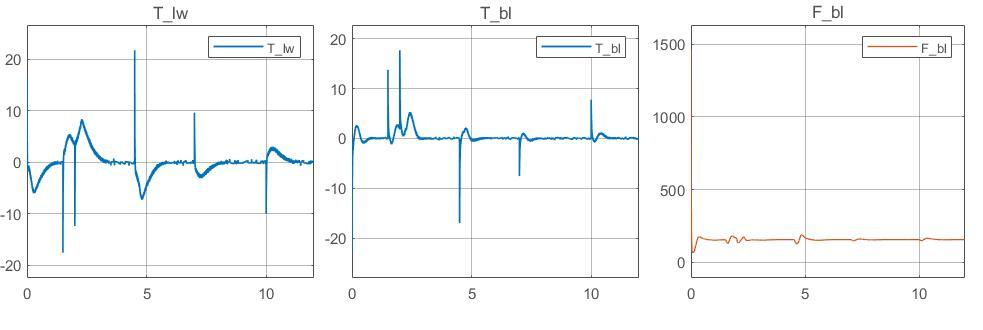

转矩